# Decimation Test Harness

Note: without Noise

## Configure input parameters:

Downsample factor 

M = 4

M = 4

Sample rate

Fs = 8000

Fs = 8000

FIR LPF filter order

N = 100

N = 100

Test signal components

f1 = 500

f1 = 500

f2 = 2000

f2 = 2000

f3 = 3500

f3 = 3500

A1 = 1

A1 = 1

A2 = 1

A2 = 1

A3 = 1

A3 = 1

## Time & test signal components

Ts = 1/Fs;
t = 0:Ts:1;
sig_in = 1/(A1+A2+A3)*(...
      A1*sin(2*pi*f1*t)...
    + A2*sin(2*pi*f2*t)...
    + A3*sin(2*pi*f3*t)...
        );

## FIR LPF

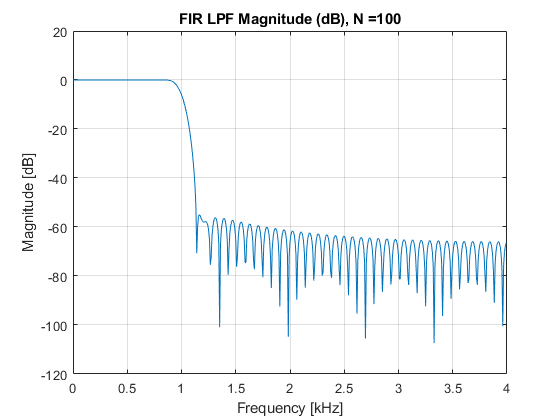

Wn = 1/M; % 1<->Fs/2 Fpass=Fcutoff/2 < Fs/(2*M)=Fs/2/M
b = fir1(N,Wn);%cut-off frequency Wn must be between 0 < Wn < 1.0,
%with 1.0 corresponding to half the sample rate
[H,w] = freqz(b,1);

figure('Name','Frequency domain: LPF','NumberTitle','off')
f = (w/pi)*Fs/2;% 0<w<pi => 0<f<Fs/2
plot(f/1000, 20*log10(abs(H))); grid on
title(['FIR LPF Magnitude (dB), ' 'N =' num2str(N)]);
xlabel('Frequency [kHz]'), ylabel('Magnitude [dB]')

## T domain

sig_out = decimate_c(sig_in,M,b);

Fs_d = Fs/M; % down-sampled sample rate
Ts_d = 1/Fs_d;

time_segment = [0, 20]

time_segment =      0    20


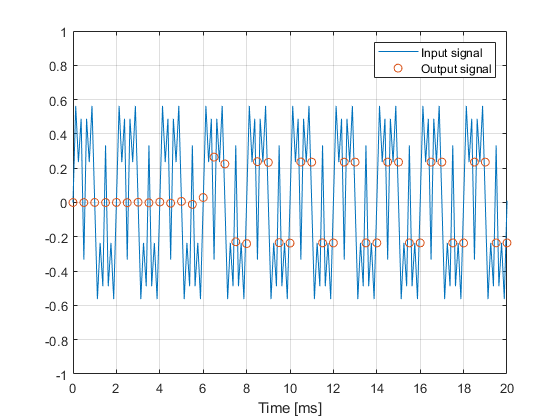

figure('Name','Time domain','NumberTitle','off')
t_axis_in = (0:length(sig_in)-1)*Ts;
t_axis_out = (0:length(sig_out)-1)*Ts_d;

plot(t_axis_in*1000, sig_in);
hold on; grid on;
plot(t_axis_out*1000, sig_out, 'o', 'MarkerSize',6);
axis([time_segment -1 1]); xlabel('Time [ms]');
legend('Input signal','Output signal');

## F domain

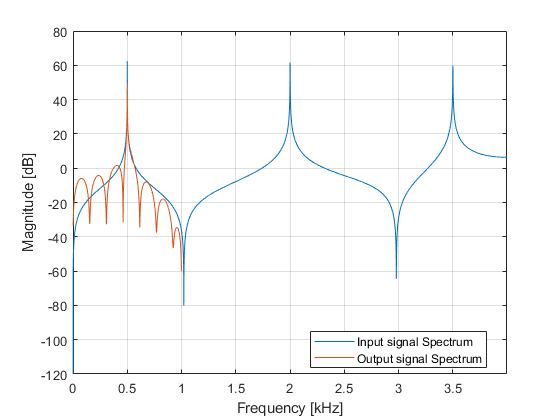

F_sig_in = fft(sig_in); 
F_sig_out = fft(sig_out);

figure('Name','Frequency domain','NumberTitle','off')
f_axis_in = (0:length(F_sig_in)/2-1)/length(F_sig_in)*Fs;
f_axis_out = (0:length(F_sig_out)/2-1)/length(F_sig_out)*Fs/M; % align axis
max_f = max(max(f_axis_in), max(f_axis_out))/1000;
plot(f_axis_in/1000, 20*log10(abs(F_sig_in(1:(length(F_sig_in)-1)/2))));
hold on; grid on;
plot(f_axis_out/1000, 20*log10(abs(F_sig_out(1:(length(F_sig_out)-1)/2))));
axis([0 max_f -120 80]); xlabel('Frequency [kHz]'), ylabel('Magnitude [dB]')
legend(["Input signal Spectrum", "Output signal Spectrum"] , 'Location','best')

%--------------------------------------------------------------------------